# Input:

% ad = '/MATLAB Drive/O/B o/0 GPS.txt';
% File path of the file
% Roof of the red car, target: ...+65 extrn
% 35 - 99 imgs

% t = 'O/Data/0 Car h a.data';
% ld = 35;
% t = 'O/Data/0 tree.data';
% t = 'O/Data/3 Car r m.data'; ld = 22;

% house 36 + px, 99 imgs+
% pix = 'O/Data/pix.data';
% m = 65; ldp = 37; tr = 21;
% pix = 'O/Data/0 tree pix.data';
% pix = 'O/Data/3 Red car m pix.data';
% m = 58;
% ldp = 44; tr = 31;
tr = 101;

fprintf('Address: %s', ad)
tbl(1:7,:)
% tbl.Ycoordinate = tbl.;
% Display the first seven rows.
ptbl(1:7,:)
% fread(fopen('/MATLAB Drive/Sir.txt', ...
%     'r'),'*char')'

# Display:

format long
% format shortG

## Altitudes, Longitudes, L`atitude`:

% idx = randperm(480) % 10
% save("O/Data/r480.mat","idx") % ,"q"

% save("id.mat","py","px","tltsa"
% ,"tltra", ...
%     "tlts","tltr","tla","tlltr","
% -append")

% load("id.mat")
% whos("-file","id.mat")
% load("O/Data/r80.mat")
% whos("-file","O/Data/r80.mat")
load("O/Data/r480.mat")
whos("-file","O/Data/r480.mat")

  Name      Size             Bytes  Class     Attributes

  idx       1x480             3840  double              



# Latitude table:

d = 'O/Data/';
t1a = readtable([d '1a Car c.txt'], ...
    'Filetype', 'text');

tla = [t1a(2:end, :); readtable([d ...
    '2a Car h a.txt'], ...
    'Filetype', 'text'); readtable([d ...
    '3a car r m.txt'], ...
    'Filetype', 'text'); readtable([d ...
    '4a Tree.txt'], ...
    'Filetype', 'text'); readtable([d ...
    '5a H.txt'], 'Filetype', 'text')];

t1o = readtable([d '1o Car c.txt'], ...
    'Filetype', 'text');

tl = [t1o(2:end, :); readtable([d ...
    '2o Car h a.txt'], ...
    'Filetype', 'text'); readtable([d ...
    '3o car r m.txt'], ...
    'Filetype', 'text'); readtable([d ...
    '4o Tree.txt'], ...
    'Filetype', 'text'); readtable([d ...
    '5o H.txt'], 'Filetype', 'text')];
% tla(:, 1).Variables = tla(:, 1 ...
%     ).Variables + .9*imnoise(tla(:, 1 ...
%     ).Variables, ['' ...
%     'gaussian'],0.05,0.01)
ntla = tla;
ntl = tl;

% sum(tla(:, 1:3).Variables - tl(:, 1:3).Variables)

ans =      0     0     0


kh = tla(:, 1).Variables;
ntla(:, 1).Variables = awgn(kh,80,'measured');
ntl(:, 1).Variables = ntla(:, 1).Variables;

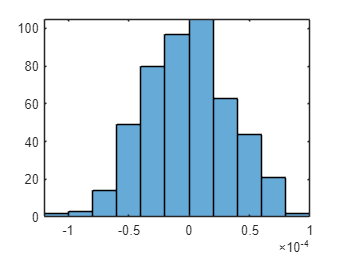

ka = tla(:, 2).Variables; snr = 130;
ntla(:, 2).Variables = awgn(ka,snr,'measured');
ntl(:, 2).Variables = ntla(:, 2).Variables;
k = tla(:, 3).Variables;
ntla(:, 3).Variables = awgn(k,snr+20,'measured');
ntl(:, 3).Variables = ntla(:, 3).Variables;

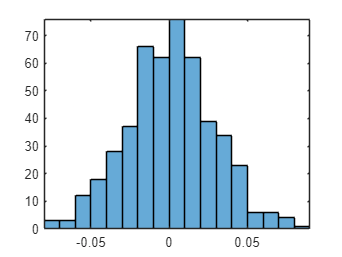

histogram(kh - awgn(kh,80,'measured'))
axis tight

histogram(ka - awgn(ka,snr,'measured'))
axis tight

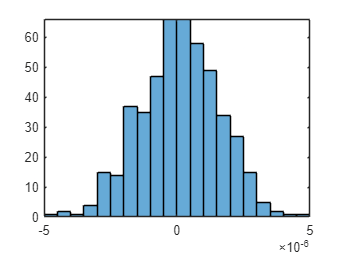

histogram(k - awgn(k,snr+20,'measured'))
axis tight

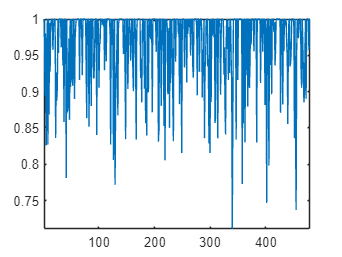

plot(imnoise( tla(:, 1).Variables, ['' ...
    'gaussian'],0.0,0.01)')
axis tight

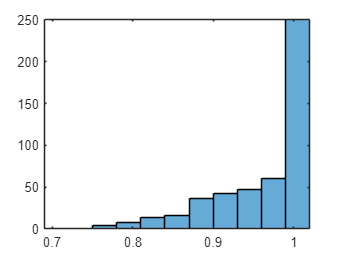

histogram((imnoise( tla(:, 1).Variables, ['' ...
    'gaussian'],0.0,.01)'))
axis tight

fprintf(['Drone data, output: Latitude\n' ...
    '9 of 100 rows, 3 of 5 cols']);
tla(2:10,:)

%// Input
Vect = [15.123, 21.345, 35.567, 45.362]

Vect =    15.1230   21.3450   35.5670   45.3620



%// Extract the decimal parts from the 
% vector elements
decimal_part = Vect - floor(Vect)

decimal_part =     0.1230    0.3450    0.5670    0.3620


## Add gaussian noise to it with zero mean

% and 0.01 variance using imnoise
noisy_decimal_part = imnoise( ...
    decimal_part, 'gaussian',0,0.001)

noisy_decimal_part =     0.1878    0.3488    0.5357    0.3999



noisy_decimal_part - decimal_part

ans =     0.0648    0.0038   -0.0313    0.0379



%// Put the noisy part back to Vect to get
% the desired output
noisy_Vect =  noisy_decimal_part +floor(Vect)

noisy_Vect =    15.1878   21.3488   35.5357   45.3999


tltr = ntla(sort(idx(tr:end)),:);
tltr(2:10,[1 3 end])

ans = 9x3 table
    Altitude    Latitude    Ylatitude
    ________    ________    _________

     174.83      47.642      47.642  
     176.52      47.642      47.642  
     177.94      47.642      47.642  
     178.61      47.642      47.642  
     180.36      47.642      47.642  
     181.27      47.642      47.642  
     182.82      47.642      47.642  
     183.96      47.642      47.642  
     185.72      47.642      47.642  


% tlts = tla(sort(idx(1:tr-1)),:);
tlts = ntla(idx(1:tr-1),:);
tlts(2:10,[1 3 end])

ans = 9x3 table
    Altitude    Latitude    Ylatitude
    ________    ________    _________

     260.66      47.637      47.637  
        259      47.637      47.641  
     246.57      47.637      47.637  
     236.81      47.637      47.641  
     236.82      47.642      47.642  
     307.27      47.638      47.641  
     231.66      47.637      47.641  
        188      47.642      47.642  
     283.22      47.642      47.642  


## Longitude table:

fprintf('Output: Longitude');tl(2:10,:)
tl(:, 1).Variables

tlltr = ntl(sort(idx(tr:end)),:);
tlltr(2:10,[1 3 end])

ans = 9x3 table
    Altitude    Latitude    Ylongitude
    ________    ________    __________

     174.83      47.642      -122.14  
     176.52      47.642      -122.14  
     177.94      47.642      -122.14  
     178.61      47.642      -122.14  
     180.36      47.642      -122.14  
     181.27      47.642      -122.14  
     182.82      47.642      -122.14  
     183.96      47.642      -122.14  
     185.72      47.642      -122.14  


% tllts = tl(sort(idx(1:tr-1)),:);
tllts = ntl(idx(1:tr-1),:);
tllts(2:10,[1 3 end])

ans = 9x3 table
    Altitude    Latitude    Ylongitude
    ________    ________    __________

     260.66      47.637      -122.14  
        259      47.637      -122.14  
     246.57      47.637      -122.14  
     236.81      47.637      -122.14  
     236.82      47.642      -122.14  
     307.27      47.638      -122.14  
     231.66      47.637      -122.14  
        188      47.642      -122.14  
     283.22      47.642      -122.14  


# Longitude gpr:

% cross-validation:
% rng('default') % For reproducibility
gprMdlo = fitrgp(tlltr, ...
    'Ylongitude', ...
    'KernelFunction', ...
    'ardsquaredexponential',...
      'FitMethod','sr','PredictMethod', ...
      'fic','Standardize',1,'Sigma',.002)

gprMdlo =   RegressionGP
           PredictorNames: {'Altitude'  'Longitude'  'Latitude'  'PixelX'  'PixelY'}
             ResponseName: 'Ylongitude'
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 380
           KernelFunction: 'ARDSquaredExponential'
        KernelInformation: [1x1 struct]
            BasisFunction: 'Constant'
                     Beta: -122.1395
                    Sigma: 0.0010
        PredictorLocation: [5x1 double]
           PredictorScale: [5x1 double]
                    Alpha: [380x1 double]
         ActiveSetVectors: [380x5 double]
            PredictMethod: 'FIC'
            ActiveSetSize: 380
                FitMethod: 'SR'
          ActiveSetMethod: 'Random'
        IsActiveSetVector: [380x1 logical]
            LogLikelihood: 2.2685e+03
         ActiveSetHistory: [1x1 struct]
           BCDInformation: []


  Properties

% ...
    %   'Standardize',1, ...
    % 'Sigma',.002)
% fprintf('kfoldLoss = %e', kfoldLoss( ...
%     cvgprMdl))
% ypred = kfoldPredict(cvgprMdl);
% fprintf('kfoldPredict: ');
% fprintf('%f\t', ypred')

ypredlo = predict(gprMdlo,tllts(:, ...
    1:end-1).Variables);ypredlo'

ans =  -122.1384 -122.1401 -122.1385 -122.1401 -122.1384 -122.1401 -122.1384 -122.1385 -122.1401 -122.1401 -122.1384 -122.1385 -122.1384 -122.1401 -122.1385 -122.1384 -122.1384 -122.1384 -122.1385 -122.1384 -122.1384 -122.1384 -122.1384 -122.1384 -122.1401 -122.1401 -122.1401 -122.1401 -122.1385 -122.1384 -122.1401 -122.1384 -122.1384 -122.1384 -122.1401 -122.1385 -122.1385 -122.1384 -122.1401 -122.1401 -122.1384 -122.1384 -122.1384 -122.1401 -122.1385 -122.1384 -122.1401 -122.1401 -122.1384 -122.1384


% elo = (lo(1)-ypredlo(1))/lo(1) %

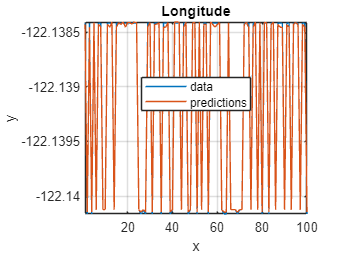

figure(); % ,'b.'
plot(tllts(:, ...
    end).Variables);
% tlltr(1:tr-1,"Ylongitude").Ylongitude
axis tight
xlabel('x')
ylabel('y')
hold on;
plot(ypredlo);
hold off;
grid on
legend({'data','predictions'}, ...
    'Location','Best');
title('Longitude')

# Laltitude gpr:

% cross-validation:
% rng('default') % For reproducibility
gprMdll = fitrgp(tltr, 'Ylatitude', ...
    'KernelFunction', ...
    'ardsquaredexponential',...
      'FitMethod','sr','PredictMethod', ...
      'fic','Standardize',1,'Sigma',.002)

gprMdll =   RegressionGP
           PredictorNames: {'Altitude'  'Longitude'  'Latitude'  'PixelX'  'PixelY'}
             ResponseName: 'Ylatitude'
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 380
           KernelFunction: 'ARDSquaredExponential'
        KernelInformation: [1x1 struct]
            BasisFunction: 'Constant'
                     Beta: 47.6395
                    Sigma: 0.0010
        PredictorLocation: [5x1 double]
           PredictorScale: [5x1 double]
                    Alpha: [380x1 double]
         ActiveSetVectors: [380x5 double]
            PredictMethod: 'FIC'
            ActiveSetSize: 380
                FitMethod: 'SR'
          ActiveSetMethod: 'Random'
        IsActiveSetVector: [380x1 logical]
            LogLikelihood: 2.2616e+03
         ActiveSetHistory: [1x1 struct]
           BCDInformation: []


  Properties, <

% ...
    %   'Standardize',1, ...
    % 'Sigma',.002)
% fprintf('kfoldLoss = %e', kfoldLoss( ...
%     cvgprMdl))
% ypred = kfoldPredict(cvgprMdl);
% fprintf('kfoldPredict: ');
% fprintf('%f\t', ypred')

ypredl = predict(gprMdll,tlts(:,1:end- ...
    1).Variables);ypredl'

ans =    47.6412   47.6375   47.6411   47.6375   47.6412   47.6419   47.6411   47.6411   47.6419   47.6419   47.6411   47.6411   47.6412   47.6419   47.6411   47.6412   47.6412   47.6412   47.6411   47.6412   47.6412   47.6411   47.6412   47.6412   47.6419   47.6375   47.6419   47.6375   47.6411   47.6412   47.6375   47.6412   47.6412   47.6412   47.6375   47.6411   47.6411   47.6412   47.6375   47.6419   47.6412   47.6412   47.6412   47.6419   47.6411   47.6412   47.6375   47.6419   47.6412   47.6412


% el = (l(1)-ypredl(1))/l(1)

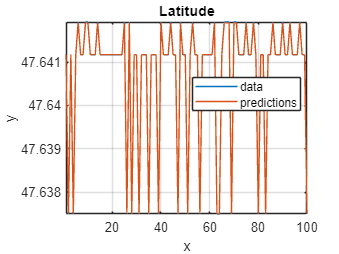

figure(); % ,'b.'
plot(tlts(:, ...
    end).Variables);
% tlltr(1:tr-1,"Ylongitude").Ylongitude
axis tight
xlabel('x')
ylabel('y')
hold on;
plot(ypredl);
hold off;
grid on
legend({'data','predictions'}, ...
    'Location','Best');
title('Latitude')

% d1km = zeros(1, tr-1);
% d2km = d1km;
% for i = 1:tr-1
%     [d1km(i), d2km(i)] = lldistkm( ...
%         [tlts(i, end ...
%     ).Variables tllts(i, end ...
%     ).Variables], ...
%     [ypredl(i) ypredlo(i)]);
% end

d1km = zeros(1, tr-1);
d2km = d1km;
ctlo = tl(idx(1:tr-1),:);
ctla = tla(idx(1:tr-1),:);
for i = 1:tr-1
    [d1km(i), d2km(i)] = lldistkm( ...
        [ctla(i, end ...
    ).Variables ctlo(i, end ...
    ).Variables], ...
    [ypredl(i) ypredlo(i)]);
end

% [d1km; d2km]*1000
% save("/MATLAB Drive/O/B o/dist." + ...
%     "mat","d2","-append")

[m, i] = min(d1km*1000); 
[M, I] = max(d1km*1000);
[m2,i2] = min(d2km*1000);
[M2,I2] = max(d2km*1000);
{m, M, m2, M2; i, I, i2, I2}'

ans = 4x2 cell array
    {[1.0384]}    {[66]}
    {[4.7984]}    {[ 3]}
    {[1.0384]}    {[66]}
    {[4.7984]}    {[ 3]}


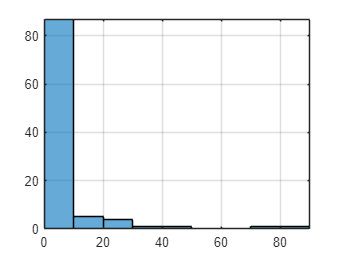

histogram(d1km*1000)
axis tight
grid on

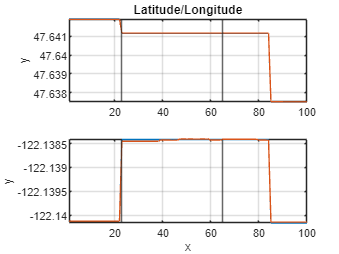

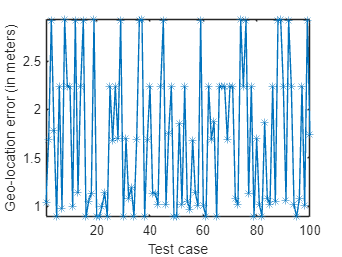

figure(); % ,'b.'
subplot(2,1,1);
plot(tlts(:, ...
    end).Variables);
% tlltr(1:tr-1,"Ylongitude").Ylongitude
axis tight
ylabel('y')
hold on;
plot(ypredl);
hold off;
grid on
% legend({'dataA','predA'}, ...
%     'Location','Best');
title('Latitude/Longitude')
xline([i,I])

subplot(2,1,2);
plot(tllts(:, ...
    end).Variables);
axis tight
xlabel('x')
ylabel('y')
hold on;
plot(ypredlo);
hold off;
grid on
% legend({'dataL','predL'}, ...
%     'Location','Best');
xline([i,I])

figure(); % ,'b.'
plot(d1km*1000,'-*');
% tlltr(1:tr-1,"Ylongitude").Ylongitude
axis tight
xlabel('Test case')
ylabel('Geo-location error (in meters)')
%grid on
%title('distance(Km)')

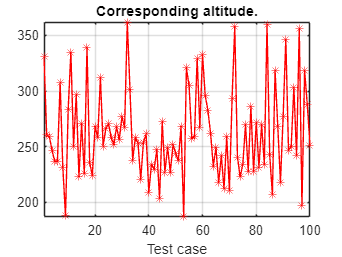

figure(); % ,'b.'
plot(tlts(:, 1).Variables,'r-*');
% tlltr(1:tr-1,"Ylongitude").Ylongitude

xlabel('Test case')
% ylabel('')
grid on
title('Corresponding altitude.')
% addpath('/MATLAB Drive/O')
% plot_darkmode % set(gca,'Color','grey')%
axis tight

[d11km, d12km] = lldistkm([tlts(1, end ...
    ).Variables tllts(1, end ...
    ).Variables], ...
    [ypredl(1) ypredlo(1)])

[d21km, d22km] = lldistkm([tla(1, end ...
    ).Variables tlltr(1, end ...
    ).Variables], ...
    [ypredl(1) ypredlo(1)])

[d1km, d2km] = lldistkm([tla(1, end ...
    ).Variables tlltr(1, end ...
    ).Variables], ...
    [ypredl(1) ypredlo(1)])

d1km*1000 % m

% writetable(tla,['O/Data/4a Tree.' ...
%     'txt'],'Delimiter',' ') % All Car h a
open 'O/Data/2a Car h a.txt'

% writetable(tl,'O/Data/4o Tree.txt',['' ...
%     'Delimiter'],' ') % Alll Car h a